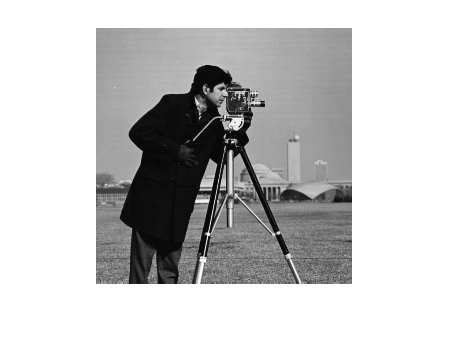

img=imread("/home/jacob/Documents/College/Sem5/DIP/LAB/cameraman.png");

imshow(img)

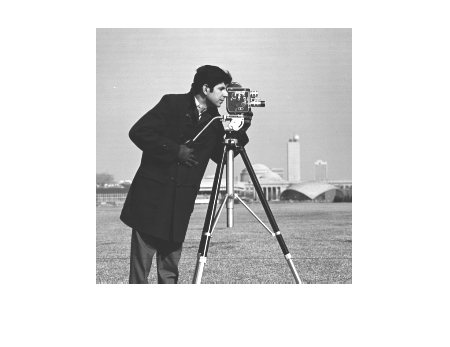

img_new = img+40;
imshow(img_new)

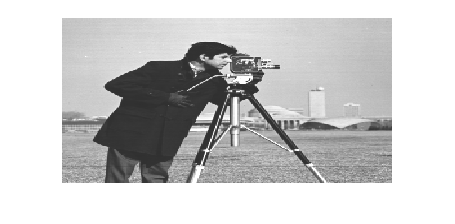


A = [];

for i = 1:size(img_new, 1)
    for j = 1:size(img_new, 2)
                A(i, j*2) = img_new(i, j);
                A(i, j*2-1) = img_new(i, j);
    end
end

resized = uint8(A);
imshow(resized)


binary=[];
thresh=150;

for r = 1:size(resized, 1)    % for number of rows of the image
    for c = 1:size(resized, 2)   % for number of columns of the image
        if resized(r,c) <= 100
            binary(r,c)=0;
        else
            binary(r,c)=1;
        end
   
    end
end

img=imread("/home/jacob/Documents/College/Sem5/DIP/LAB/cameraman.png");

imshow(img)

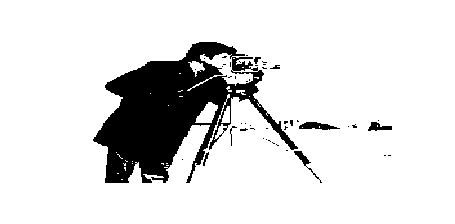

imshow(binary)

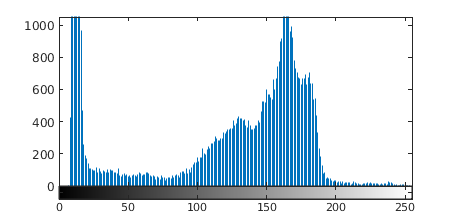


imhist(img);

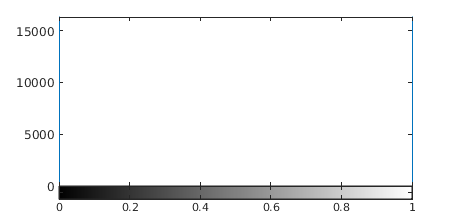

imhist(binary);